clear;

0.134

ans = 0.1340

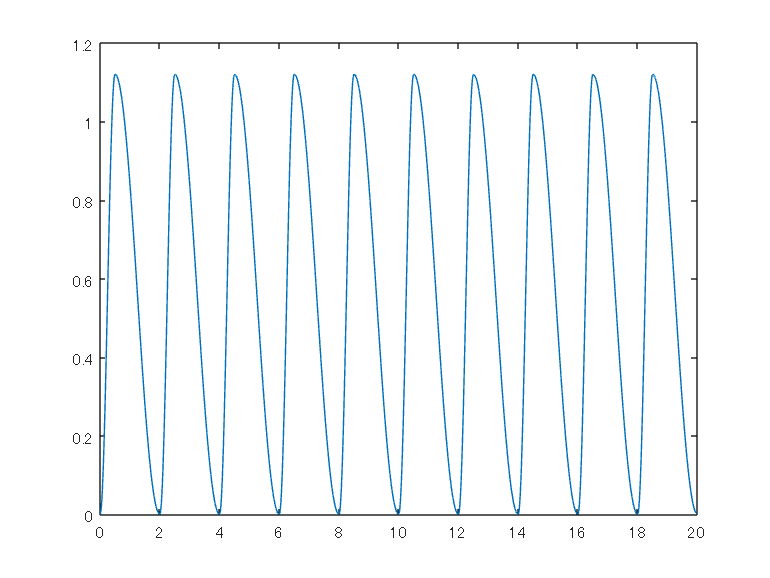


repnum = 10;
dt = 0.01;
n = 2;
t = (0:dt:repnum*n-dt).';

forwardRate = 1;
backwardRate = 3;

t_forward = (0:dt:(n-dt)*(forwardRate)/(forwardRate + backwardRate)).';
t_backward = (0:dt:(n-dt)*(backwardRate)/(forwardRate + backwardRate)).';

L= 1.12;
slider_forward = L*(cos(pi*t_forward/(n*forwardRate/(forwardRate + backwardRate)) - pi) + 1)/2;
slider_backward = L*(cos(pi*t_backward/(n*backwardRate/(forwardRate + backwardRate))) + 1)/2;

slider = repmat([slider_forward; slider_backward], [repnum, 1]);
figure;
plot(t, slider);

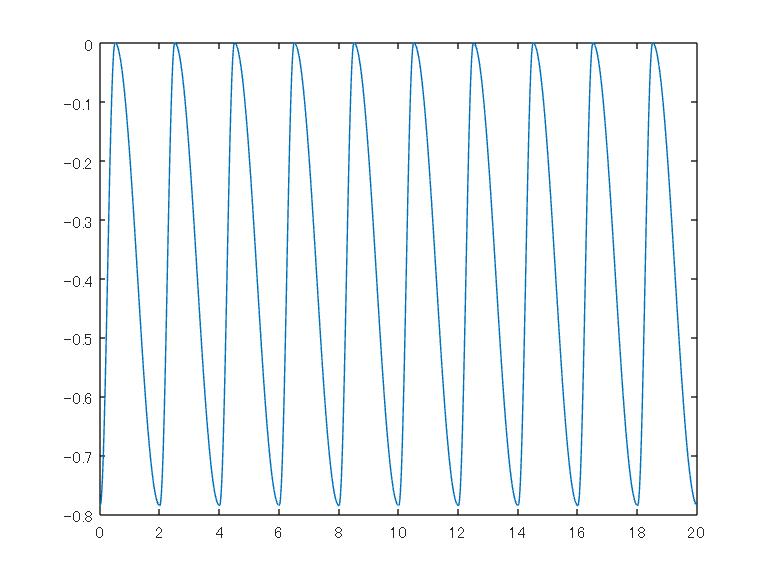


L= pi/4;
pitch_forward = L*(cos(pi*t_forward/(n*forwardRate/(forwardRate + backwardRate)) + pi) - 1)/2;
pitch_backward = L*(cos(pi*t_backward/(n*backwardRate/(forwardRate + backwardRate))) - 1)/2;
pitch = repmat([pitch_forward; pitch_backward], [repnum, 1]);

figure;
plot(t, pitch)

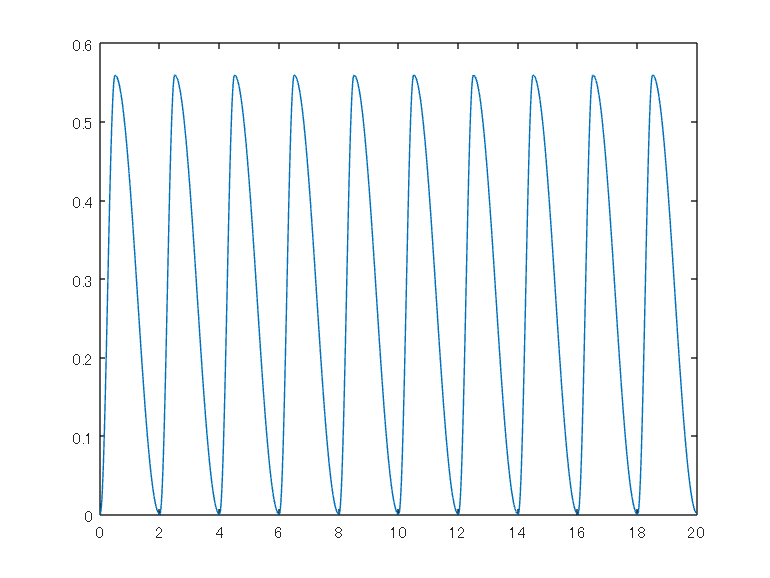


L= 0.559;
stretch_forward = L*(cos(pi*t_forward/(n*forwardRate/(forwardRate + backwardRate)) - pi) + 1)/2;
stretch_backward = L*(cos(pi*t_backward/(n*backwardRate/(forwardRate + backwardRate))) + 1)/2;
stretch = repmat([stretch_forward; stretch_backward], [repnum, 1]);

figure;
plot(t, stretch);

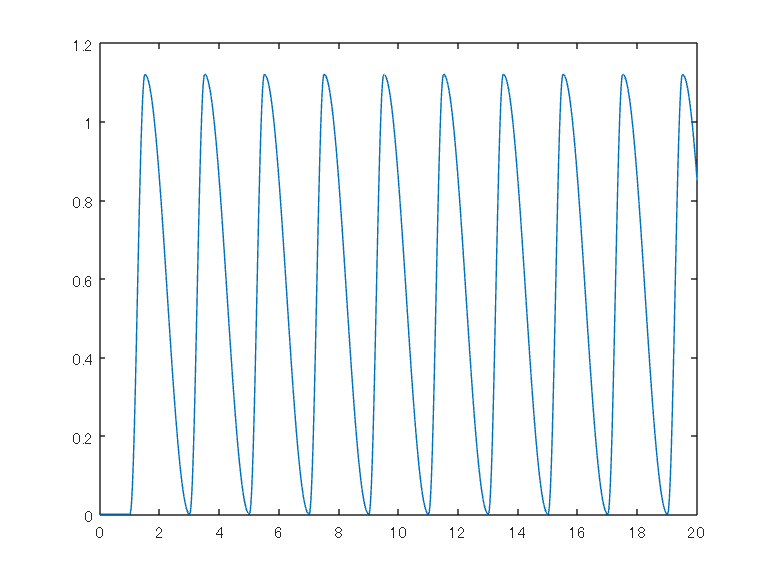



halfT = (0:dt:n/2-dt).';

slider_left = [zeros([length(halfT), 1]); slider(1:end-length(halfT))];
figure;
plot(t, slider_left);

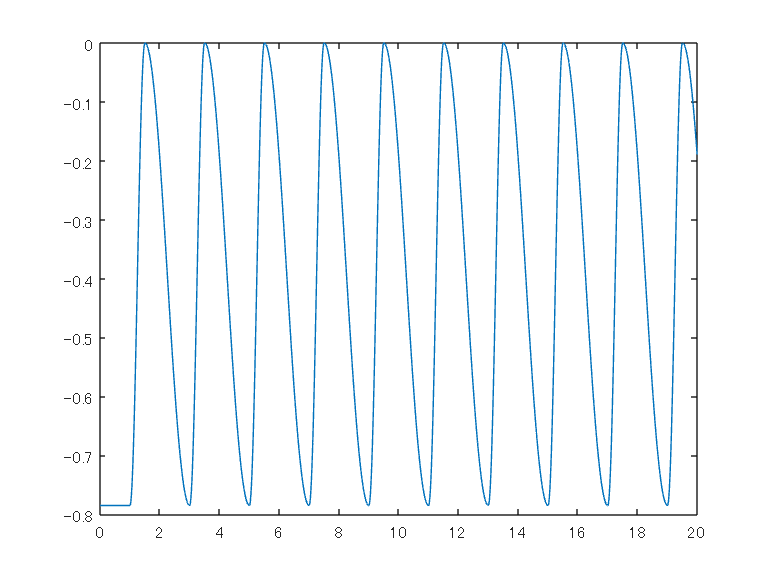

pitch_left = [-pi/4 + zeros([length(halfT), 1]); pitch(1:end-length(halfT))];
figure;
plot(t, pitch_left);

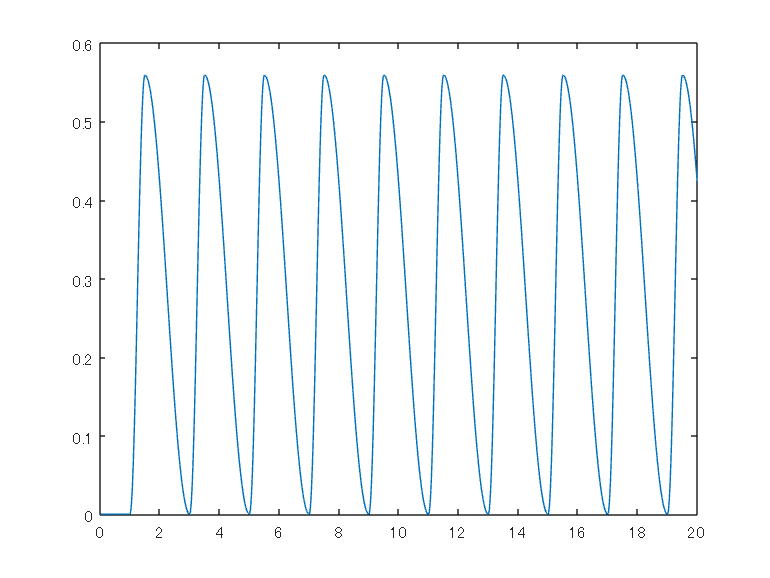


stretch_left = [zeros([length(halfT), 1]); stretch(1:end-length(halfT))];
figure;
plot(t, stretch_left);

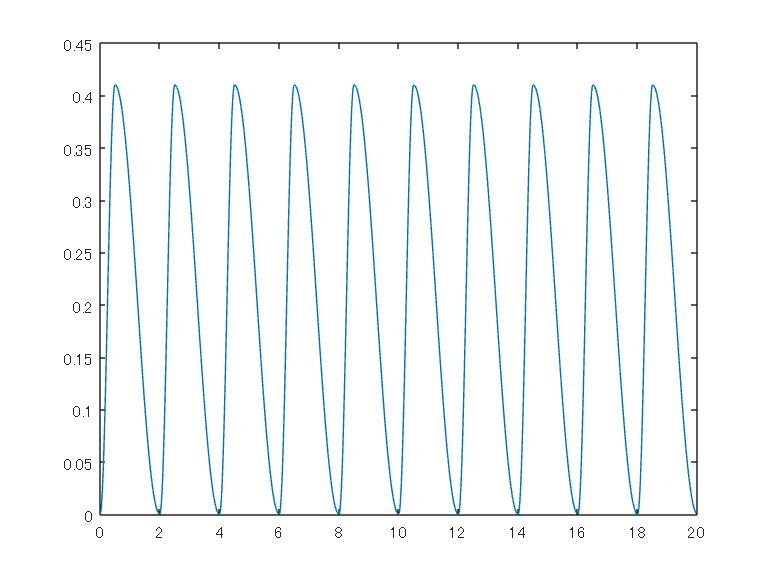


forwardRate = 1;
backwardRate = 3;

t_forward = (0:dt:(n-dt)*(forwardRate)/(forwardRate + backwardRate)).';
t_backward = (0:dt:(n-dt)*(backwardRate)/(forwardRate + backwardRate)).';

L = 0.41;

chairLeftSlider_forward = L*(cos(pi*t_forward/(n*forwardRate/(forwardRate + backwardRate)) - pi) + 1)/2;
chairLeftSlider_backward = L*(cos(pi*t_backward/(n*backwardRate/(forwardRate + backwardRate))) + 1)/2;

chairLeftSlider = repmat([chairLeftSlider_forward; chairLeftSlider_backward], [repnum, 1]);
figure;
plot(t, chairLeftSlider);

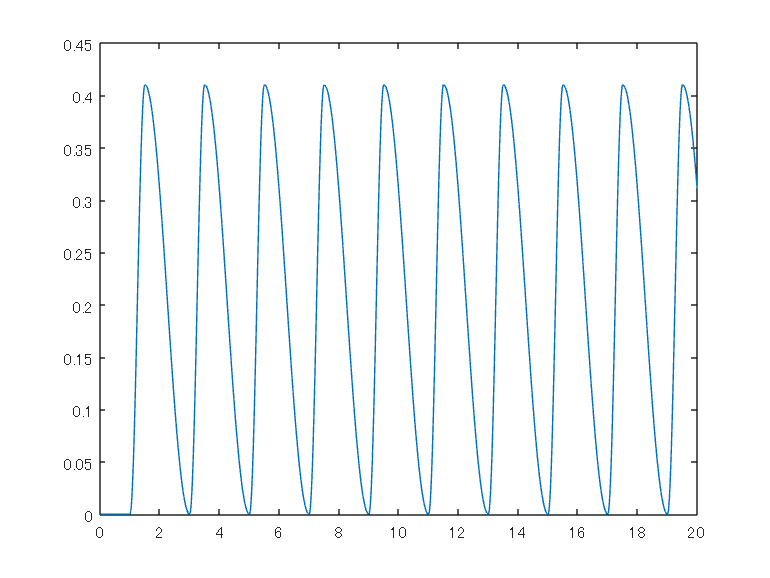

chairRightSlider = [zeros([length(halfT), 1]); chairLeftSlider(1:end-length(halfT))];
figure;
plot(t, chairRightSlider);

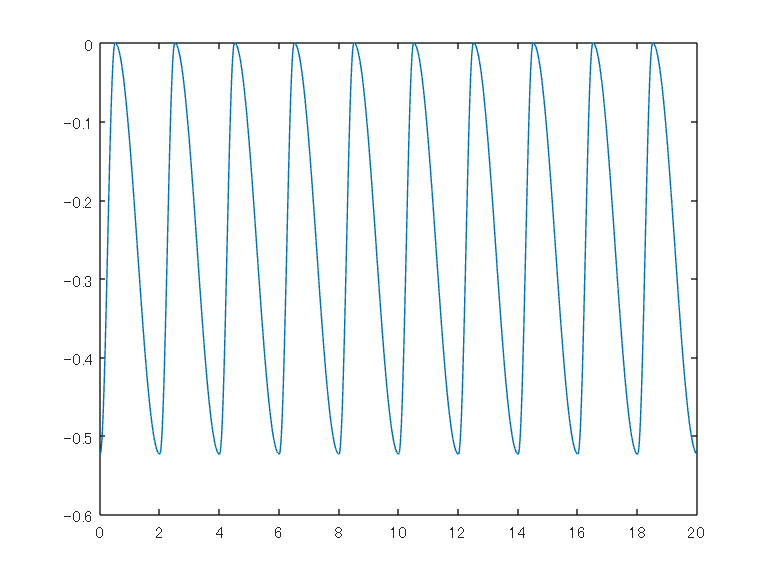


L= -pi/6;
chairLeftPedal_forward = L*(cos(pi*t_forward/(n*forwardRate/(forwardRate + backwardRate))) + 1)/2;
chairLeftPedal_backward = L*(cos(pi*t_backward/(n*backwardRate/(forwardRate + backwardRate)) + pi) + 1)/2;
chairLeftPedal = repmat([chairLeftPedal_forward; chairLeftPedal_backward], [repnum, 1]);

figure;
plot(t, chairLeftPedal);

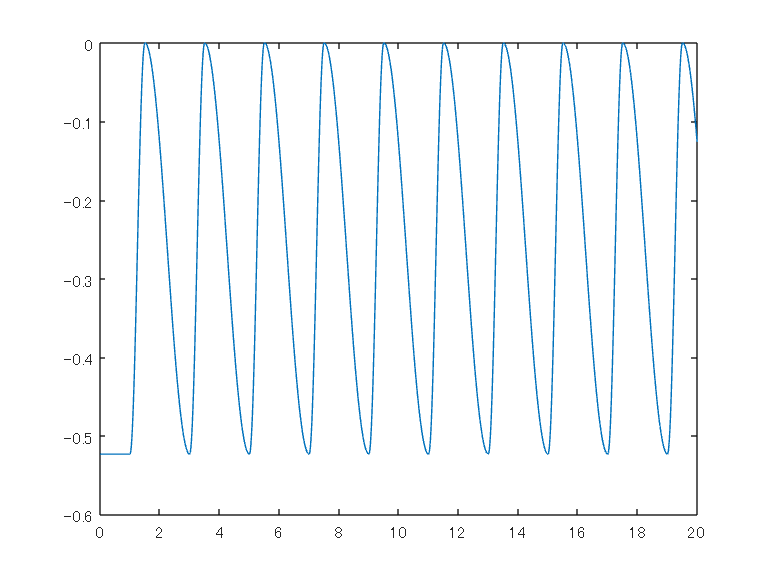

chairRightPedal = [L + zeros([length(halfT), 1]); chairLeftPedal(1:end-length(halfT))];
figure;
plot(t, chairRightPedal);

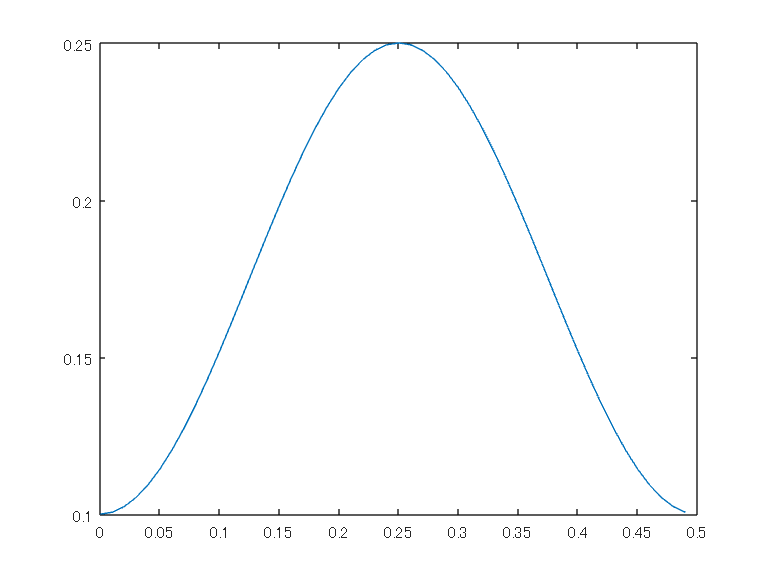

L = 0.15;
offset = 0.1;
% chairLifter = L*(cos(4*pi*t/n + pi) + 1)/2 + 0.1;
tUpDown = (0:dt:(n-dt)*(forwardRate)/(forwardRate + backwardRate)).';
chairLifterUpDown = L*(cos(2*pi*tUpDown/(n*forwardRate/(forwardRate + backwardRate)) + pi) + 1)/2 + offset;
chairLifterSleep = offset + 0 .* ( 0:dt:n*abs(0.5 - forwardRate/(forwardRate + backwardRate)) - dt).';

chairLifter = repmat([chairLifterUpDown; chairLifterSleep], [2*repnum, 1]);
figure;
plot(tUpDown, chairLifterUpDown)

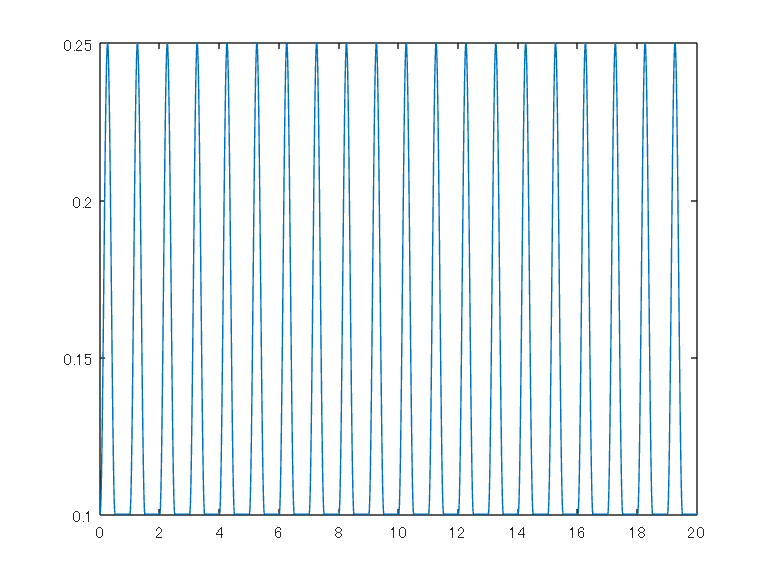


figure;
plot(t, chairLifter);




SignalStickRightSlider = timeseries(slider, t);
SignalStickLeftSlider = timeseries(slider_left, t);
SignalStickRightPitch = timeseries(pitch, t);
SignalStickLeftPitch = timeseries(pitch_left, t);
SignalStickRightStretch = timeseries(stretch, t);
SignalStickLeftStretch = timeseries(stretch_left, t);
SignalChairLeftSlider = timeseries(chairLeftSlider, t);
SignalChairRightSlider = timeseries(chairRightSlider, t);
SignalChairLeftPedal = timeseries(chairLeftPedal, t);
SignalChairRightPedal = timeseries(chairRightPedal, t);
SignalChairLifter = timeseries(chairLifter, t);

Scenario = Simulink.SimulationData.Dataset;

Scenario{1} = SignalStickRightSlider;
Scenario{1}.Name = 'SignalStickRightSlider';
Scenario{2} = SignalStickRightPitch;
Scenario{2}.Name = 'SignalStickRightPitch';
Scenario{3} = SignalStickRightStretch;
Scenario{3}.Name = 'SignalStickRightStretch';
Scenario{4} = SignalStickLeftSlider;
Scenario{4}.Name = 'SignalStickLeftSlider';
Scenario{5} = SignalStickLeftPitch;
Scenario{5}.Name = 'SignalStickLeftPitch';
Scenario{6} = SignalStickLeftStretch;
Scenario{6}.Name = 'SignalStickLeftStretch';
Scenario{7} = SignalChairLeftSlider;
Scenario{7}.Name = 'SignalChairLeftSlider';
Scenario{8} = SignalChairLeftPedal;
Scenario{8}.Name = 'SignalChairLeftPedal';
Scenario{9} = SignalChairRightSlider;
Scenario{9}.Name = 'SignalChairRightSlider';
Scenario{10} = SignalChairRightPedal;
Scenario{10}.Name = 'SignalChairRightPedal';
Scenario{11} = SignalChairLifter;
Scenario{11}.Name = 'SignalChairLifter';


save('scenario.mat', 'Scenario');